## **Part 1: Digital synthesis of arbitrary waveforms with specified SNR**

### Background

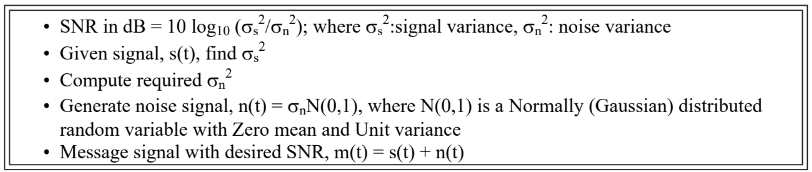

Procedure Overview

• Synthesize a 1 second A-Sharp sinusoidal tone (466.16 Hz) sampled at 8 kHz.

• Plot this waveform; observe and listen using the sound command in Matlab.

• Corrupt this signal with a Gaussian noise source to get an SNR of 10 dB. Observe, listen and save waveform as before.

• Synthesize 1 cycle of the noisy waveform.

• Vary the frequency, amplitude.

    Repeat experiment with various SNRs.

• Experiment with other waveforms:

Example Matlab Code

%ECOMMS Lab Project 1 Example
%S. Mandayam, Rowan University
%This program generates a 1-second duration
%Asharp signal (466.16 Hz) with a specified SNR
%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
pause(2);

%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
pause(2);

%Add signal to noise and generate message
m=s+n;
sound(m);

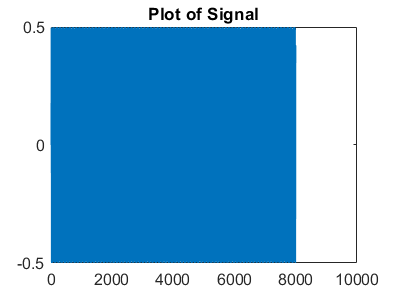

%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
plot(s)
pause(2);
title("Plot of Signal")

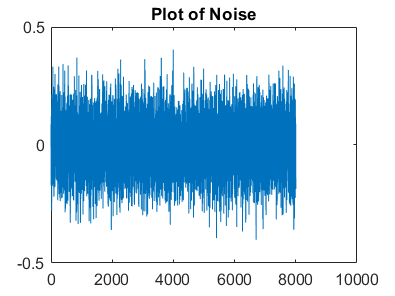


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (n)
title("Plot of Noise")
pause(2);

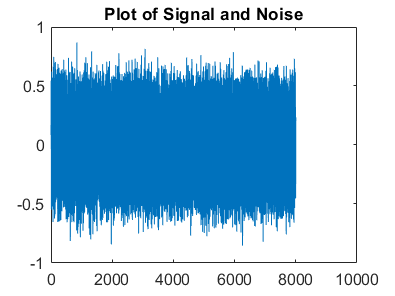


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(m)
title("Plot of Signal and Noise")


%Specify SNR
snr=20;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
plot(s)
pause(2);
title("Plot of Signal")

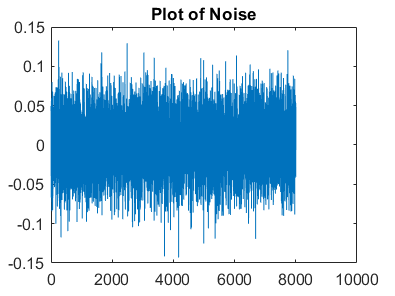


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (n)
title("Plot of Noise")
pause(2);

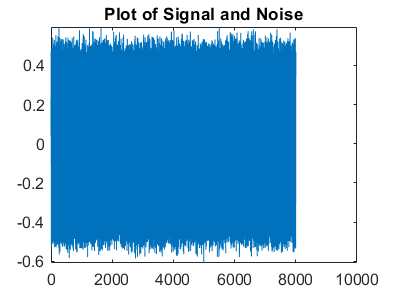


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(m)
title("Plot of Signal and Noise")


%Specify SNR
snr=30;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
plot(s)
pause(2);
title("Plot of Signal")

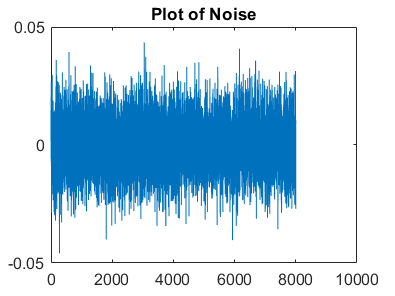


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (n)
title("Plot of Noise")
pause(2);

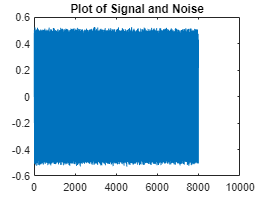


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(m)
title("Plot of Signal and Noise")

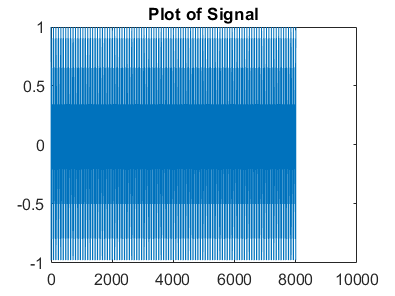



%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5.*(1+cos(2*pi*100*t)).*cos(2*pi*1000*t);
sound(s);
plot(s)
pause(2);
title("Plot of Signal")

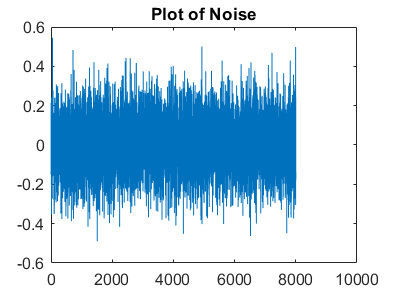


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (n)
title("Plot of Noise")
pause(2);

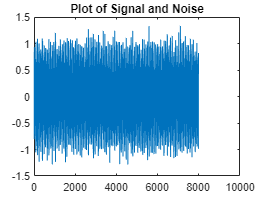


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(m)
title("Plot of Signal and Noise")

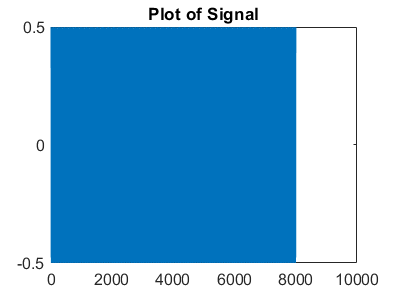



%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*cos(2*pi*1000*t+sin(2*pi*100*t));
sound(s);
plot(s)
pause(2);
title("Plot of Signal")

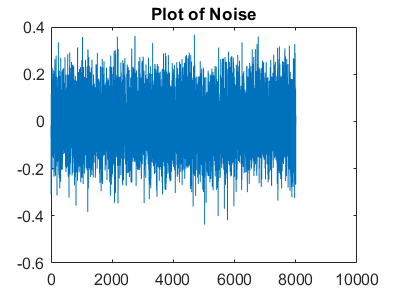


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (n)
title("Plot of Noise")
pause(2);

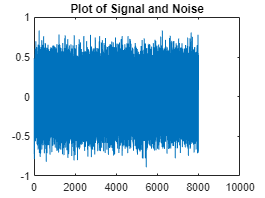


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(m)
title("Plot of Signal and Noise")